# Similarity Transform

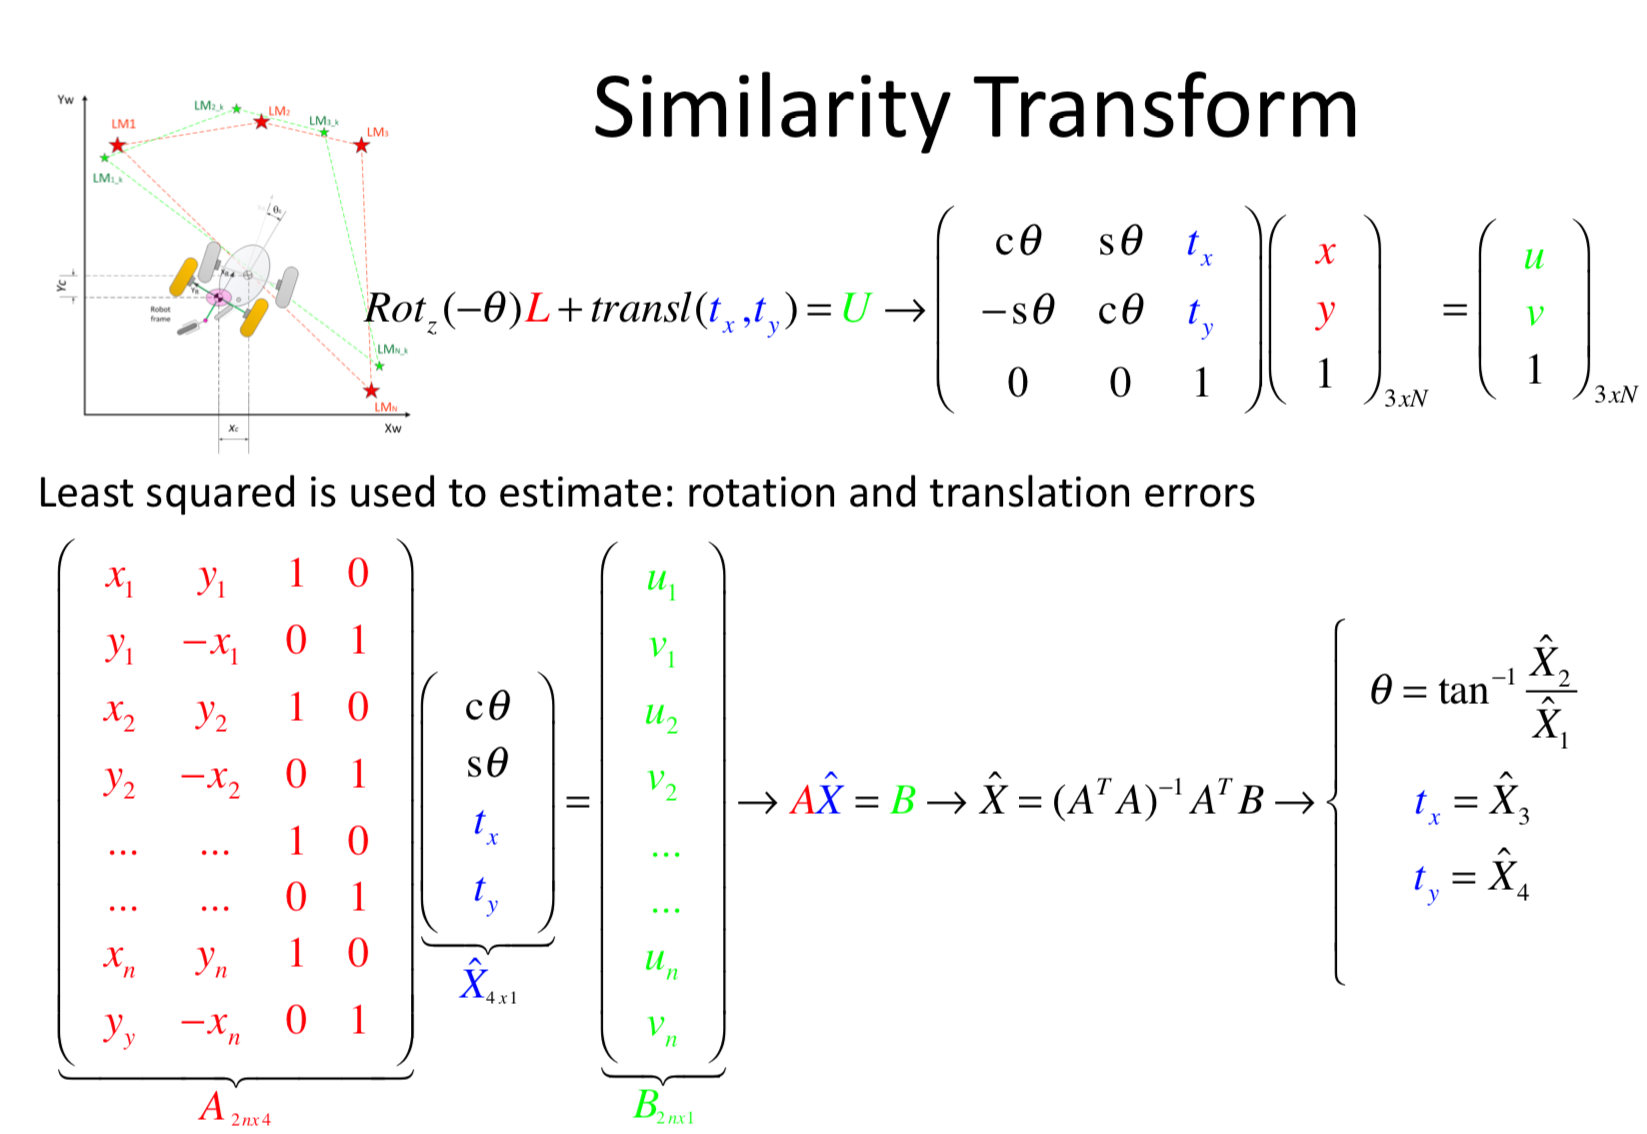

## Land Mark

They are known

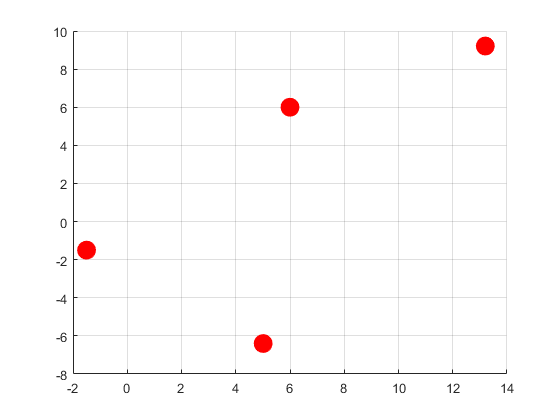

LandMark = [  13.2,9.21; 6,6; -1.5,-1.5;  5.01, -6.4]';
figure
axis ([-2 2 -8 10])
scatter(LandMark(1,:),LandMark(2,:),200, 'r','filled');
grid on

## Simulating innovation

Using Postmultiplication: Translate an rotate the Land Marks

alpha = pi/16 % Rotate pi/16 rad --> 22.5 degrees

alpha = 0.1963

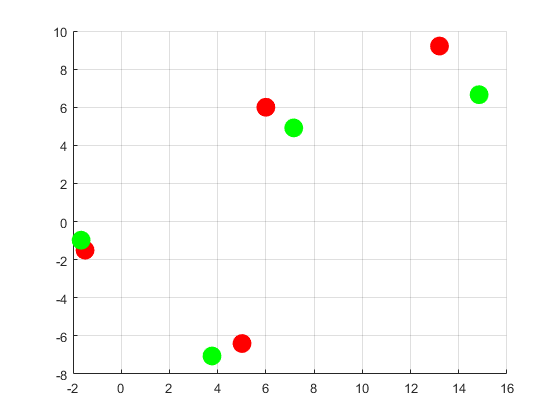

tx = 0.1; % Translate 
ty = 0.2;
RotzTxy = [cos(alpha), sin(alpha), tx;...
          -sin(alpha), cos(alpha), ty;...
           0,           0,          1];
Innovation = RotzTxy*[LandMark;ones(1,4)];
hold on;
scatter(Innovation(1,:), Innovation(2,:),200, 'g','filled');

## Building the Matrices

A = [];
for i=1:size(LandMark, 2)
    A = [A;[LandMark(1,i),LandMark(2,i),1,0]];
    A = [A;[LandMark(2,i),-LandMark(1,i),0,1]]
end

A =    13.2000    9.2100    1.0000         0
    9.2100  -13.2000         0    1.0000


A =    13.2000    9.2100    1.0000         0
    9.2100  -13.2000         0    1.0000
    6.0000    6.0000    1.0000         0
    6.0000   -6.0000         0    1.0000


A =    13.2000    9.2100    1.0000         0
    9.2100  -13.2000         0    1.0000
    6.0000    6.0000    1.0000         0
    6.0000   -6.0000         0    1.0000
   -1.5000   -1.5000    1.0000         0
   -1.5000    1.5000         0    1.0000


A =    13.2000    9.2100    1.0000         0
    9.2100  -13.2000         0    1.0000
    6.0000    6.0000    1.0000         0
    6.0000   -6.0000         0    1.0000
   -1.5000   -1.5000    1.0000         0
   -1.5000    1.5000         0    1.0000
    5.0100   -6.4000    1.0000         0
   -6.4000   -5.0100         0    1.0000


B = [];%Build Matrix B
for i=1:size(Innovation, 2)
    B = [B; Innovation(1,i); Innovation(2,i)]
end

B =    14.8431
    6.6578


B =    14.8431
    6.6578
    7.1553
    4.9142


B =    14.8431
    6.6578
    7.1553
    4.9142
   -1.6638
   -0.9785


B =    14.8431
    6.6578
    7.1553
    4.9142
   -1.6638
   -0.9785
    3.7652
   -7.0544


## Finding the error in pose

X = inv((A'*A))*A'*B;
tx_ST = X(3)

tx_ST = 0.1000

ty_ST = X(4)

ty_ST = 0.2000

alpha_ST = atan2(X(2),X(1))

alpha_ST = 0.1963

## Comparing 

tx

tx = 0.1000

ty

ty = 0.2000

alpha

alpha = 0.1963